mask = ncread('data/mask.nc','mask');
mask = reshape(mask,[size(mask,1),size(mask,2),1,1]);
mask = repmat(mask,[1,1,12,29]);

file = 'data/satellite_socat_NACCOM.nc';
sss = ncread(file,'sss') .* mask;
sst = ncread(file,'sst') .* mask;
chla = ncread(file,'chla') .* mask;
sla = ncread(file,'sla') .* mask;
adt = ncread(file,'adt') .* mask;
wspd = ncread(file,'wspd');
fco2 = ncread(file,'fco2_socat') .* mask;
pco2air = ncread(file,'pco2air') .* mask;
lon = ncread(file,'lon');
lat = ncread(file,'lat');

year = [1993:2021];
month = [1:12];

fco2(fco2<1) = nan;
sla(sla<-10) = nan;
sss(sss<-10) = nan;
sst(sst<-10) = nan;
chla(chla<0) = nan;
pco2air(pco2air<200) = nan;
% 
% fco2(:,181:end,:,:) = nan;
% sst(:,181:end,:,:) = nan;
idxseplon = nanmax(find(lon<=-100));
fco2(1:idxseplon,:,:,:) = nan;
% fco2(1:29,:,:) = nan;

ssh_err = ncread('data/err_sst_and_ssh.nc','ssh_err_4d');
sst_err = ncread('data/err_sst_and_ssh.nc','sst_err_4d');

ssh_err = ssh_err(:);
sst_err = sst_err(:);

[lat_msh, lon_msh] = meshgrid(lat,lon);
lat_msh = repmat(reshape(lat_msh,[520,220,1,1]),[1,1,12,29]);
lon_msh = repmat(reshape(lon_msh,[520,220,1,1]),[1,1,12,29]);
month_msh = repmat(reshape(month,[1,1,12,1]),[520,220,1,29]);

% highlat
fco2_i = fco2;
sss_i = sss;
sst_i = sst;
chla_i = chla;
sla_i = sla;
adt_i = adt;
pco2air_i = pco2air;
lon_i = lon_msh;
lat_i = lat_msh;
mon_i = month_msh;
wspd_i = wspd;

fco2_train = nan(size(fco2));
sss_train = nan(size(fco2));
sst_train = nan(size(fco2));
chla_train = nan(size(fco2));
sla_train = nan(size(fco2));
adt_train = nan(size(fco2));
pco2air_train = nan(size(fco2));
lat_train = nan(size(fco2));
lon_train = nan(size(fco2));
mon_train = nan(size(fco2));
wspd_train = nan(size(fco2));

fco2_test = nan(size(fco2));
sss_test = nan(size(fco2));
sst_test = nan(size(fco2));
chla_test = nan(size(fco2));
sla_test = nan(size(fco2));
adt_test = nan(size(fco2));
pco2air_test = nan(size(fco2));
lat_test = nan(size(fco2));
lon_test = nan(size(fco2));
mon_test = nan(size(fco2));
wspd_test = nan(size(fco2));

idx_test = [2004:2005]-1992;
idx_train = [1993:2021]-1992;
idx_train(idx_test) = [];

fco2_train(:,:,:,idx_train) = fco2_i(:,:,:,idx_train);
sss_train(:,:,:,idx_train) = sss_i(:,:,:,idx_train);
sst_train(:,:,:,idx_train) = sst_i(:,:,:,idx_train);
chla_train(:,:,:,idx_train) = chla_i(:,:,:,idx_train);
sla_train(:,:,:,idx_train) = sla_i(:,:,:,idx_train);
adt_train(:,:,:,idx_train) = adt_i(:,:,:,idx_train);
pco2air_train(:,:,:,idx_train) = pco2air_i(:,:,:,idx_train);
lat_train(:,:,:,idx_train) = lat_msh(:,:,:,idx_train);
lon_train(:,:,:,idx_train) = lon_msh(:,:,:,idx_train);
mon_train(:,:,:,idx_train) = month_msh(:,:,:,idx_train);
wspd_train(:,:,:,idx_train) = wspd_i(:,:,:,idx_train);

fco2_test(:,:,:,idx_test) = fco2_i(:,:,:,idx_test);
sss_test(:,:,:,idx_test) = sss_i(:,:,:,idx_test);
sst_test(:,:,:,idx_test) = sst_i(:,:,:,idx_test);
chla_test(:,:,:,idx_test) = chla_i(:,:,:,idx_test);
sla_test(:,:,:,idx_test) = sla_i(:,:,:,idx_test);
adt_test(:,:,:,idx_test) = adt_i(:,:,:,idx_test);
pco2air_test(:,:,:,idx_test) = pco2air_i(:,:,:,idx_test);
lat_test(:,:,:,idx_test) = lat_msh(:,:,:,idx_test);
lon_test(:,:,:,idx_test) = lon_msh(:,:,:,idx_test);
mon_test(:,:,:,idx_test) = month_msh(:,:,:,idx_test);
wspd_test(:,:,:,idx_test) = wspd_i(:,:,:,idx_test);

idxout_traintrain = nan(size(fco2));
idxout_traintest = nan(size(fco2));
idxout_test = nan(size(fco2));

idxout_traintrain_flat = idxout_traintrain(:);
idxout_traintest_flat = idxout_traintrain(:);
idxout_test_flat = idxout_traintrain(:);

T_train = [lon_train(:),lat_train(:),mon_train(:),sss_train(:),sst_train(:),adt_train(:),pco2air_train(:),fco2_train(:)];
T_test = [lon_test(:),lat_test(:),mon_test(:),sss_test(:),sst_test(:),adt_test(:),pco2air_test(:),fco2_test(:)];

idx_all = [1:size(T_train,1)];
ivalid_train = ~isnan(sum(T_train,2));
idx_all_valid = idx_all(ivalid_train);

T_train_input = T_train(ivalid_train,:);

seed = 100;
rng(seed);

idxtraintest = randperm(size(T_train_input,1),floor(0.2*size(T_train_input,1)));
idxtraintrain = [1:size(T_train_input,1)];
idxtraintrain(idxtraintest) = [];

idx_traintrain = idx_all_valid(idxtraintrain);
idx_traintest = idx_all_valid(idxtraintest);

T_train_train = T_train_input(idxtraintrain,:);
T_train_test = T_train_input(idxtraintest,:);

ivalid_test = ~isnan(sum(T_test,2));
T_test_input = T_test(ivalid_test,:);

idxout_test_flat(ivalid_test) = 1.0;
idxout_validation = reshape(idxout_test_flat,size(idxout_test));

idxout_traintrain_flat(idx_traintrain) = 1.0;
idxout_traintest_flat(idx_traintest) = 1.0;

idxout_train = reshape(idxout_traintrain_flat,size(idxout_test));
idxout_test = reshape(idxout_traintest_flat,size(idxout_test));

T_train_train = T_train(~isnan(idxout_traintrain_flat),:);
T_train_test = T_train(~isnan(idxout_traintest_flat),:);
T_test_input = T_test(~isnan(idxout_test_flat),:);

[trainedModel, validationPredictions, validationRMSE] = trainRFER7(T_train_train);

T_all = [lon_msh(:),lat_msh(:),month_msh(:),sss(:),sst(:),adt(:),pco2air(:)];
ivalid_all = ~isnan(sum(T_all,2));
T_all_input = T_all(ivalid_all,:);

ssh_err_input = ssh_err(ivalid_all);
sst_err_input = sst_err(ivalid_all);

u_sst = 0.23;
u_sss = 0.6;
u_ssh = 0.018;
u_u10 = 0.901;
u_pco2air = 0.22;

pco2_out = trainedModel.predictFcn(T_all_input);

N_test = 100;
diff_pco2_sss = nan(size(T_all_input,1),N_test);
% Test SSS sensitivity
for itest = 1:N_test
    T_all_i = T_all_input;
    ei = normrnd(0,u_sss,size(T_all_input,1),1);
    T_all_i(:,4) = T_all_input(:,4) + ei;
    y_test_1 = trainedModel.predictFcn(T_all_i);
    diff_pco2_sss(:,itest) = y_test_1 - pco2_out;
end

% % Test WSPD sensitivity
% diff_pco2_u10 = nan(size(T_all_input,1),N_test);
% for itest = 1:N_test
%     T_all_i = T_all_input;
%     ei = normrnd(0,u_u10,size(T_all_input,1),1);
%     T_all_i(:,7) = T_all_input(:,7) + ei;
%     y_test_1 = trainedModel.predictFcn(T_all_i);
%     diff_pco2_u10(:,itest) = y_test_1 - pco2_out;
% end

% Test pCO2air sensitivity
diff_pco2_pco2air = nan(size(T_all_input,1),N_test);
for itest = 1:N_test
    T_all_i = T_all_input;
    ei = normrnd(0,u_pco2air,size(T_all_input,1),1);
    T_all_i(:,7) = T_all_input(:,7) + ei;
    y_test_1 = trainedModel.predictFcn(T_all_i);
    diff_pco2_pco2air(:,itest) = y_test_1 - pco2_out;
end

% Test SST sensitivity
diff_pco2_sst = nan(size(T_all_input,1),N_test);
for itest = 1:N_test
    T_all_i = T_all_input;
    ei = nan(size(sst_err_input));
    for i = 1:length(ei)
        ei(i) = normrnd(0,sst_err_input(i));
    end
    T_all_i(:,5) = T_all_input(:,5) + ei;
    y_test_1 = trainedModel.predictFcn(T_all_i);
    diff_pco2_sst(:,itest) = y_test_1 - pco2_out;
end             

% Test ADT sensitivity
diff_pco2_ssh = nan(size(T_all_input,1),N_test);
% Test SSS sensitivity
for itest = 1:N_test                    
    T_all_i = T_all_input;                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          
    ei = nan(size(ssh_err_input));
    for i = 1:length(ei)
        ei(i) = normrnd(0,ssh_err_input(i));
    end
    T_all_i(:,6) = T_all_input(:,6) + ei;
    y_test_1 = trainedModel.predictFcn(T_all_i);
    diff_pco2_ssh(:,itest) = y_test_1 - pco2_out;
end

diff_pco2_sss_avg = nanstd(diff_pco2_sss,0,2);
diff_pco2_sst_avg = nanstd(diff_pco2_sst,0,2);
diff_pco2_ssh_avg = nanstd(diff_pco2_ssh,0,2);
% diff_pco2_u10_avg = nanstd(diff_pco2_u10,0,2);
diff_pco2_pco2air_avg = nanstd(diff_pco2_pco2air,0,2);
% diff_pco2_all = sqrt(diff_pco2_sss_avg.^2 + diff_pco2_sst_avg.^2 + diff_pco2_ssh_avg.^2 + diff_pco2_u10_avg.^2 + diff_pco2_pco2air_avg.^2);
diff_pco2_all = sqrt(diff_pco2_sss_avg.^2 + diff_pco2_sst_avg.^2 + diff_pco2_ssh_avg.^2 + diff_pco2_pco2air_avg.^2);

% save('data/SF_fco2_4d.mat','SF_sss','SF_sst','SF_adt','SF_wspd','SF_pco2air','lon','lat','-mat');

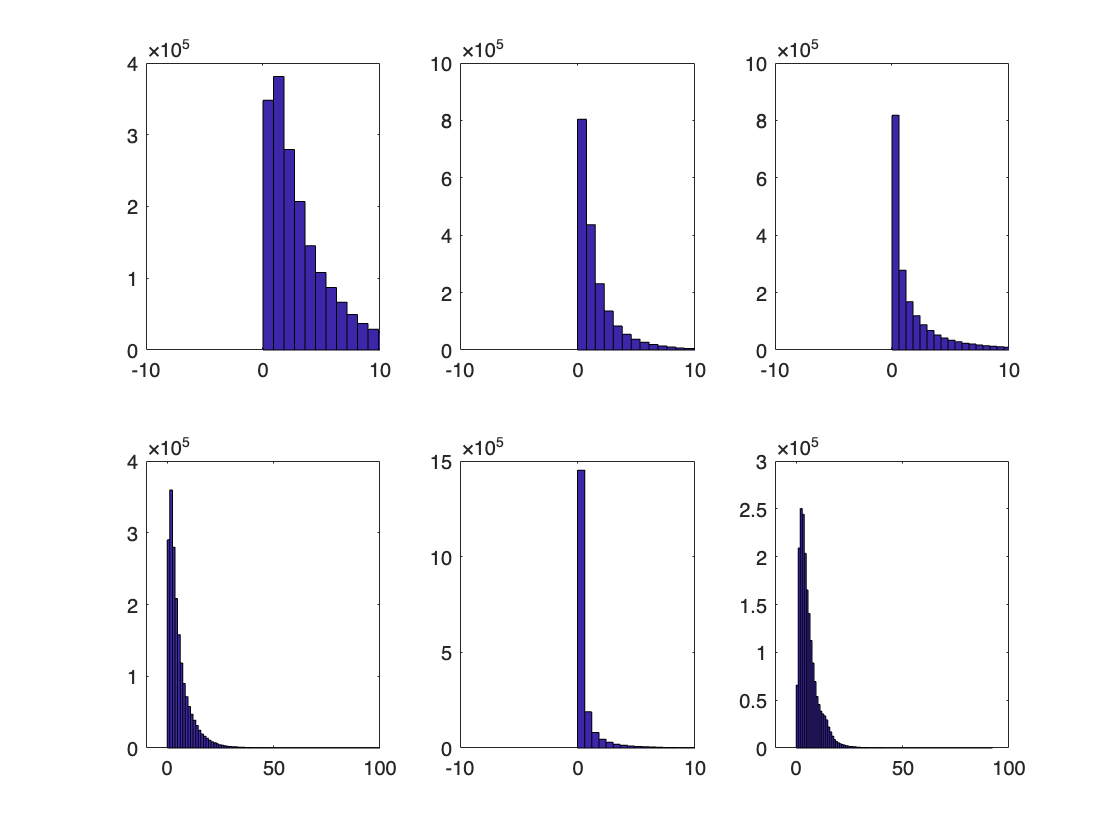

subplot(2,3,1);
hist(diff_pco2_sss_avg,100);
xlim([-10,10]);

subplot(2,3,2);
hist(diff_pco2_sst_avg,100);
xlim([-10,10]);

subplot(2,3,3);
hist(diff_pco2_ssh_avg,100);
xlim([-10,10]);

subplot(2,3,4);
hist(diff_pco2_u10_avg,100);
xlim([-10,100]);

subplot(2,3,5);
hist(diff_pco2_pco2air_avg,100);
xlim([-10,10]);

subplot(2,3,6);
hist(diff_pco2_all,100);
xlim([-10,100]);

diff_sss_withnan = nan(size(sst_err));
diff_sss_withnan(ivalid_all) = diff_pco2_sss_avg;
diff_sss_withnan = reshape(diff_sss_withnan,size(fco2));

diff_sst_withnan = nan(size(sst_err));
diff_sst_withnan(ivalid_all) = diff_pco2_sst_avg;
diff_sst_withnan = reshape(diff_sst_withnan,size(fco2));

diff_ssh_withnan = nan(size(sst_err));
diff_ssh_withnan(ivalid_all) = diff_pco2_ssh_avg;
diff_ssh_withnan = reshape(diff_ssh_withnan,size(fco2));

diff_pco2air_withnan = nan(size(sst_err));
diff_pco2air_withnan(ivalid_all) = diff_pco2_pco2air_avg;
diff_pco2air_withnan = reshape(diff_pco2air_withnan,size(fco2));

diff_all_withnan = nan(size(sst_err));
diff_all_withnan(ivalid_all) = diff_pco2_all;
diff_all_withnan = reshape(diff_all_withnan,size(fco2));

save('data/uncertainty.mat','diff_all_withnan','diff_sss_withnan','diff_sst_withnan','diff_ssh_withnan','diff_pco2air_withnan');